## Conexión con el Robot.

Se busca en las conexiones USB y se espera el comando.

Robot = ArduinoManager();

Initializing Arduino Manager...
Scanning ports: COM8
Probing COM8... SUCCESS! Arduino found.


## Inicialización.

Moviendo los servos a 90º

Robot.setServos(0, 0);
 

## Posiciones nuevas

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = 0

P1 = 0

P2 = 75

P2 = 75

[x, y] = cinem_directa_analitica(P1, P2)

x = 11.1235

y = 13.5230

[xd, yd] = cinematica_DH(P1, P2)

xd = 9.4411

yd = 7.2444

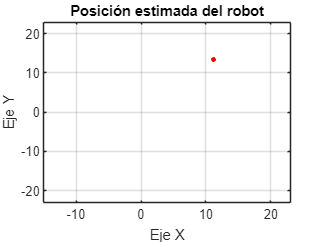

figure(1)
plot(x, y, 'r.', 'MarkerSize', 10)
        hold on
        grid on
        xlim([-15, 23]);
        ylim([-23, 23]);
        xlabel('Eje X'); ylabel('Eje Y');
        title('Posición estimada del robot');
        hold off

## Enviar comando

Robot.setServos(P1, P2);

 

## Actualización continua

Con los "sliders" puedes seleccionar las nuevas posiciones del robot.

P1 = 17;
P2 = -2;
Robot.setServos(P1, P2);
[x, y] = cinem_directa_analitica(P1, P2)
[xd, yd] = cinematica_DH(P1, P2)
 

## Cinemática directa y espacio de trabajo

EspacioDeTrabajo();
 

## Uso de la cinemática inversa

Introduce las coordenadas X, Y deseadas. 

Asegurate que pertenezcan al espacio de trabajo!

X = 12.1                        
Y = -16.69
[P1, P2] = ik_geometrica(X, Y)
Robot.setServos(P1, P2);
 

qMatrix = TrayectoriaArticular(15.7674, 13.5359, 17.3097, -12.5442);

qMatrix = TrayectoriaCartesiana(15.7674, 13.5359, 17.3097, -12.5442);

Robot.ejecutarTrayectoria(qMatrix, 2)
 